CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('ContourData_S_EE=0.024_7D_HHigherRes_rIL6.mat','ContourData_7D')

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ContourData_7D.C_EE;

C_EI = ContourData_7D.C_EI;

C_IE = ContourData_7D.C_IE;

C_II = ContourData_7D.C_II;

## The 2nd one of S_Ilgn: MF Contour Plot

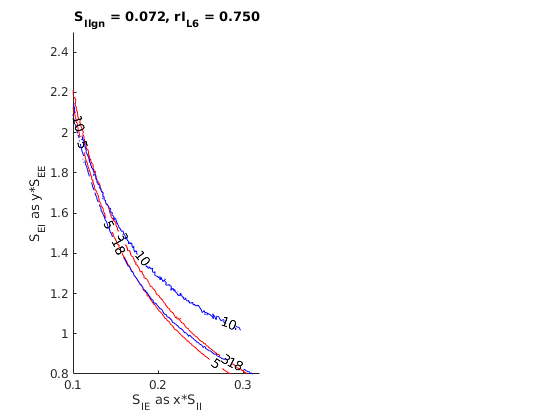

S_EEnow = ContourData_7D.S_EE;
S_IInow = ContourData_7D.S_II;
figure('Name','Contour Validation')
S_IlgnInd = 1; S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
rI_L6Ind  = 3; rI_L6now  = ContourData_7D.rI_L6test(rI_L6Ind);
        
    subplot 121    
    hold on
    CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,:,S_IlgnInd,rI_L6Ind));
    CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind)); 
    CurrentFrE(CurrentFrE<eps) = nan; CurrentFrE(CurrentBlowup == 1) = nan;
    CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind)); 
    CurrentFrI(CurrentFrI<eps) = nan; CurrentFrI(CurrentBlowup == 1) = nan;
    [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrE,[3  5 ],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrI,[10 18],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
    rI_L6txt = sprintf('%.3f',rI_L6now);
    title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')

    %xlim([0.06 0.5])

## Set up Network Simulation

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
% load('Initials.mat')
%parameters
S_EE = ContourData_7D.S_EE; S_II = ContourData_7D.S_II; %S_IE and S_EI will be tested
p_EEFail = ContourData_7D.p_EEFail; S_amb = ContourData_7D.S_amb;

tau_ampa_R = ContourData_7D.tau_ampa_R; tau_ampa_D = ContourData_7D.tau_ampa_D;
tau_nmda_R = ContourData_7D.tau_nmda_R; tau_nmda_D = ContourData_7D.tau_nmda_D;
tau_gaba_R = ContourData_7D.tau_gaba_R; tau_gaba_D = ContourData_7D.tau_ampa_D;
tau_ref = ContourData_7D.tau_ref; % time unit is ms
dt = 0.2;
gL_E = ContourData_7D.gL_E;  Ve = ContourData_7D.Ve; S_Elgn = ContourData_7D.S_Elgn; 
rhoE_ampa = ContourData_7D.rhoE_ampa; rhoE_nmda = ContourData_7D.rhoE_nmda;
gL_I = ContourData_7D.gL_I;  Vi = ContourData_7D.Vi; S_Ilgn = S_Ilgnnow;             
rhoI_ampa = ContourData_7D.rhoI_ampa; rhoI_nmda = ContourData_7D.rhoI_nmda;

% LGN input
lambda_E = ContourData_7D.lambda_E; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = ContourData_7D.lambda_I; 

% Check amb. That's for differnet figures
rE_amb = ContourData_7D.rE_amb; rI_amb = ContourData_7D.rI_amb;
% L6 input
S_EL6 = ContourData_7D.S_EL6; rE_L6 = ContourData_7D.rE_L6;
S_IL6 = ContourData_7D.S_IL6; rI_L6 = rI_L6now; %250hz for now

% Length of the interval %% Replace S_EI by testing values
EITestN = 10;
S_IEtest = [0.14,0.19]*S_II;
S_EItest(1,:) = linspace(1.5,1.7,EITestN)*S_EE;    
S_EItest(2,:) = linspace(1.1,1.3,EITestN)*S_EE;  

## MF Estimation, repeat

% cluster = gcp('nocreate');
% if isempty(cluster)
%     cluster = parpool([4 64]);
%     cluster.IdleTimeout = 1200;
% end

Fr_NoFix_ref = zeros(2,EITestN,length(S_IEtest));
mV_NoFix_ref = zeros(2,EITestN,length(S_IEtest));
Fr_NoFixVar_ref = zeros(2,EITestN,length(S_IEtest));
mV_NoFixVar_ref = zeros(2,EITestN,length(S_IEtest));
Fr_NoFixTraj_ref = cell(EITestN,length(S_IEtest));
mV_NoFixTraj_ref = cell(EITestN,length(S_IEtest));

loopCount_ref = zeros(EITestN,length(S_IEtest)); % count the number of loops
ConvIndi_ref = logical(loopCount_ref);
FailureIndicate = logical(loopCount_ref);

SampleNum = 100;
MaxNum = 500;
h = 1;
SimuT = 20*1e3;
tic
for S_IEInd = 1:length(S_IEtest)
    S_IE = S_IEtest(S_IEInd);
    S_EItestNow = S_EItest(S_IEInd,:);
for S_EIInd = 1:length(S_EItestNow)
    S_EI = S_EItestNow(S_EIInd);
    tic
    [Fr_NoFixTraj_ref{S_EIInd,S_IEInd},mV_NoFixTraj_ref{S_EIInd,S_IEInd},...
        loopCount_ref(S_EIInd,S_IEInd),    ConvIndi_ref(S_EIInd,S_IEInd),...
        FailureIndicate(S_EIInd,S_IEInd)]...
                  = MeanFieldEst_BkGd_Indep_StepSize_ref_testL6(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            S_EL6,S_IL6,rE_L6,rI_L6,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,MaxNum,h,SimuT);
                                        
    toc
end
end

Elapsed time is 5.891039 seconds.
Elapsed time is 5.101584 seconds.
Elapsed time is 4.712285 seconds.
Elapsed time is 4.634723 seconds.
Elapsed time is 4.656972 seconds.
Elapsed time is 4.662384 seconds.
Elapsed time is 4.571633 seconds.
Elapsed time is 4.599878 seconds.
Elapsed time is 4.543643 seconds.
Elapsed time is 4.540012 seconds.
Elapsed time is 3.655575 seconds.
Elapsed time is 5.424940 seconds.
Elapsed time is 4.779877 seconds.
Elapsed time is 4.700658 seconds.
Elapsed time is 4.709792 seconds.
Elapsed time is 4.661734 seconds.
Elapsed time is 4.637475 seconds.
Elapsed time is 4.532748 seconds.
Elapsed time is 4.568872 seconds.
Elapsed time is 4.598291 seconds.


toc

Elapsed time is 4.601067 seconds.



for S_IEInd = 1:length(S_IEtest)
for S_EIInd = 1:length(S_EItest)
    Fr_NoFix_ref(:,S_EIInd,S_IEInd) = mean(Fr_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    mV_NoFix_ref(:,S_EIInd,S_IEInd) = mean(mV_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar_ref(:,S_EIInd,S_IEInd) = var(Fr_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar_ref(:,S_EIInd,S_IEInd) = var(mV_NoFixTraj_ref{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
end
end

## Network Simulation

S_EE = 0.024, S_EI = 0.0408, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

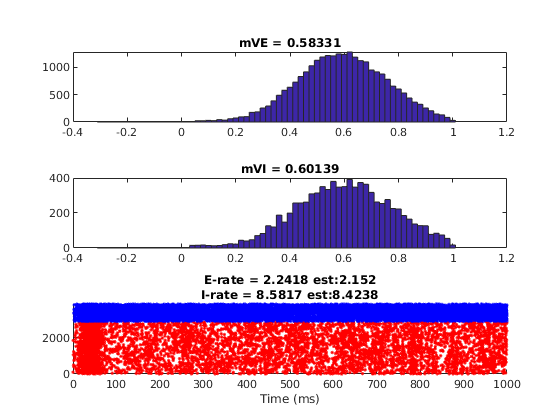

S_EE = 0.024, S_EI = 0.0408, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

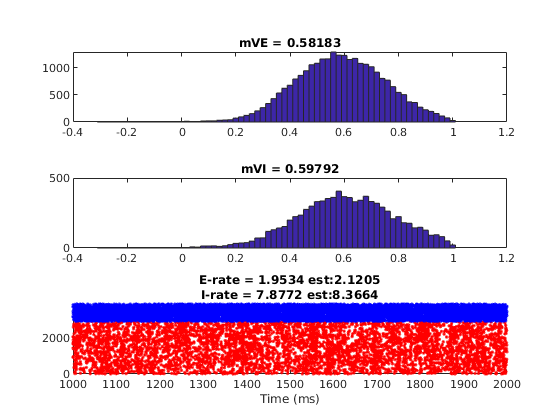

S_EE = 0.024, S_EI = 0.0408, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

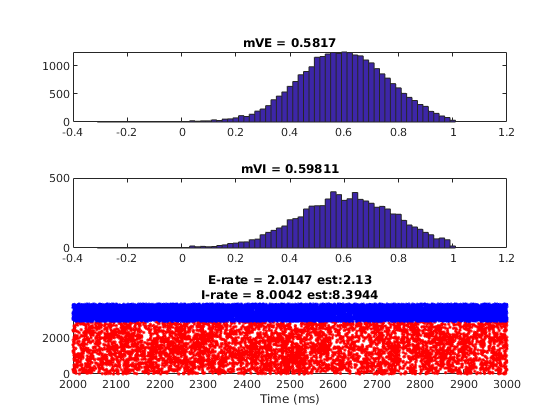

S_EE = 0.024, S_EI = 0.040267, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.040267, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.040267, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.039733, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.039733, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.039733, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0392, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0392, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0392, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038667, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038667, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038667, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038133, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038133, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.038133, S_IE = 0.0168, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

warning!: Network exploded
warning!: Network exploded
warning!: Network exploded
warning!: Network exploded


S_EE = 0.024, S_EI = 0.0312, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

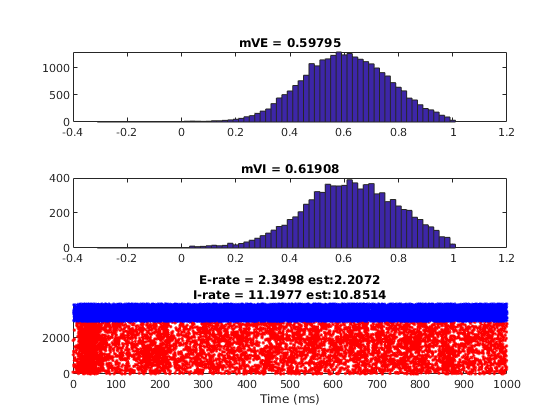

S_EE = 0.024, S_EI = 0.0312, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0312, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

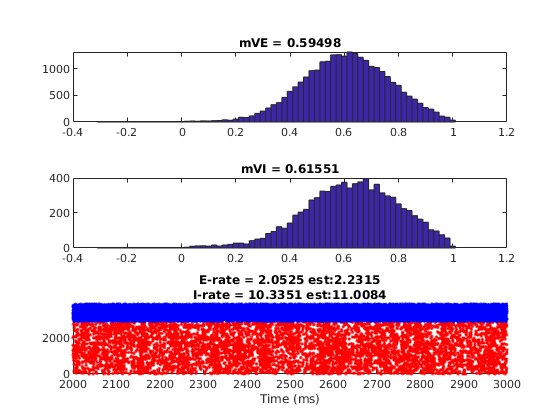

S_EE = 0.024, S_EI = 0.030667, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

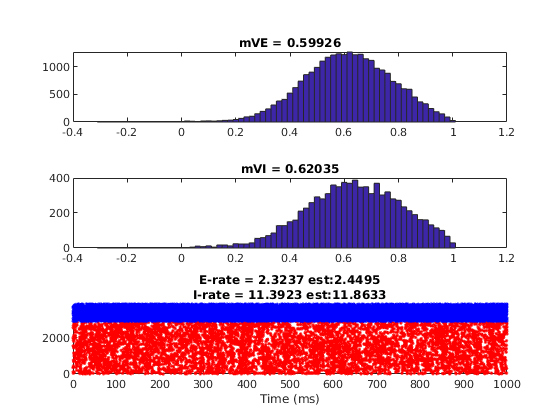

S_EE = 0.024, S_EI = 0.030667, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

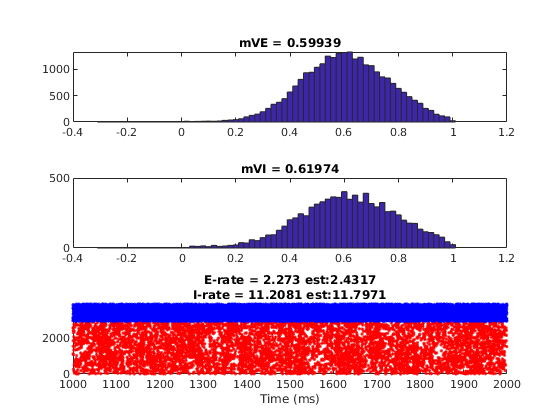

S_EE = 0.024, S_EI = 0.030667, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.030133, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

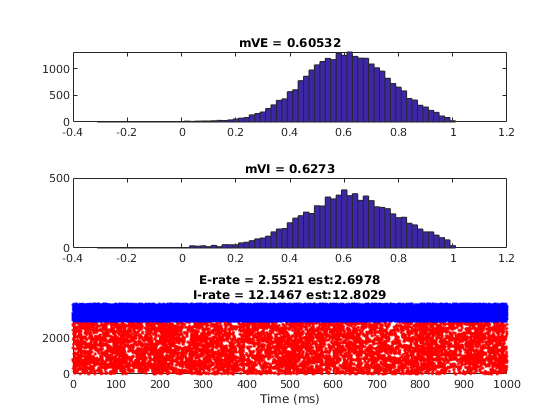

S_EE = 0.024, S_EI = 0.030133, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

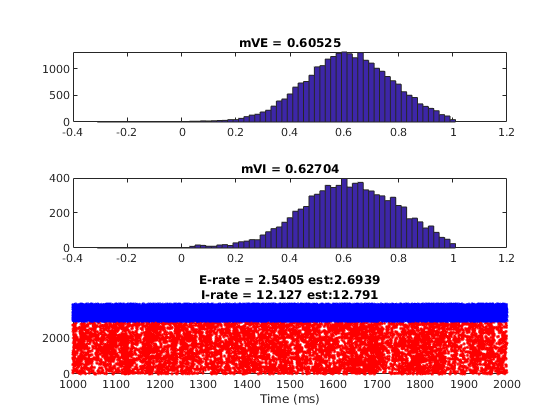

S_EE = 0.024, S_EI = 0.030133, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0296, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0296, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.0296, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.029067, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.029067, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

S_EE = 0.024, S_EI = 0.029067, S_IE = 0.0228, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.072, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

warning!: Network exploded
warning!: Network exploded
warning!: Network exploded
warning!: Network exploded
warning!: Network exploded



T = 3000; sampleT = 2; SimulationT = 1000;
% Setup Results Recording

Fr_NW      = zeros(2,EITestN,length(S_IEtest));
mV_NW      = zeros(2,EITestN,length(S_IEtest));
Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute 
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
    
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

for S_IEInd = 1:length(S_IEtest)
    load('Initials.mat')
    S_IE = S_IEtest(S_IEInd);
    S_EItestNow = S_EItest(S_IEInd,:);
for S_EIInd = length(S_EItestNow):-1:1
    S_EI = S_EItestNow(S_EIInd);
    %E_SpHis= []; I_SpHis=[];
    E_Sp = []; I_Sp = [];
    VE_T = []; VI_T = [];
    sampleN = floor(sampleT/dt); % sample each 2 ms
    SimulationN = floor(SimulationT/dt); % show and check every 200ms
    
    BlowUp = false;
    for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,...
          oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
     oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
          oGI_ampa_D,oGI_nmda_D,oGI_gaba_D] = ...
          V1NetworkUpdate_L6(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,...
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
                          S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
                          S_EL6,S_IL6,rE_L6,rI_L6);
                      
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
                                              GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
                                              GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;

% When reaching every 200ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>500
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
                         ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
                         'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
                         ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
    
    fprintf(ParameterDisp)
    h = figure('Name','TestRaster');
    subplot 311
    hist(oVE,-0.3:0.02:1)
    title(['mVE = ' num2str(nanmean(VE_T))])
    %E_SpHis = [E_SpHis,sum(oSpE)];
    %axis([-0.4 1.1 0 6000])
    
    subplot 312
    hist(oVI,-0.3:0.02:1)
    title(['mVI = ' num2str(nanmean(VI_T))])
    %I_SpHis = [I_SpHis,sum(oSpI)];
    %axis([-0.4 1.1 0 2000])
    
    

    %E_Ind = 10000:13000; I_Ind = 3300:4300;
    scatterE = find(ismember(E_Sp(:,1),E_Ind));
    scatterI = find(ismember(I_Sp(:,1),I_Ind));
    [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
    [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

    WinSize = SimulationT;
    T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
    E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
    I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
    E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
    I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

    f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                   S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                   lambda_E,S_Elgn,rE_amb,S_amb,...
                                   lambda_I,S_Ilgn,rI_amb,...
                                   S_EL6,S_IL6,rE_L6,rI_L6,...
                                   gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));

    subplot 313
    hold on
    scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
    scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
    title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
    xlabel('Time (ms)')
    xlim(T_RateWindow)
    ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
    drawnow
    %pause
    close(h)
    
    end

    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.95*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    end
    
    if BlowUp
        continue
    else
    Fr_NW(:,S_EIInd,S_IEInd)      = [E_Rate;I_Rate];
    mV_NW(:,S_EIInd,S_IEInd)      = [nanmean(VE_T),nanmean(VI_T)];
    Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
    end
    

end    
end